clear;
close all;

addpath('./DCS_functions')

## Electromagnet

EM.num = 1;
EM.ai = 3.75e-3; % inner radius (m)
EM.ao = 6.00e-3; % outer radius (m)
EM.l =  4.00e-3; % length (m)

EM.Nturns = 60 * ones(1,EM.num);

EM_pos = [0, 0, 6.5e-3]; % (m)
EM = SetPositionRotation(EM, EM_pos, [1,0,0], deg2rad(0));

EM.current_density = 1; % (A/m^2) 

## Sensor

Sensor.num = 2;
Sensor.side_length_z = 0.4e-3;
Sensor.side_length_xy = 0.8e-3;

Sensor_pos1 = EM_pos + [6e-3 0 -2e-3];
Sensor_pos2 = EM_pos + [-6e-3 0 -2e-3];
Sensor = SetPositionRotation(Sensor, [Sensor_pos1;Sensor_pos2], [1,0,0;1,0,0], [0;0]);
clear EM_pos Sensor_pos1 Sensor_pos2

## Model

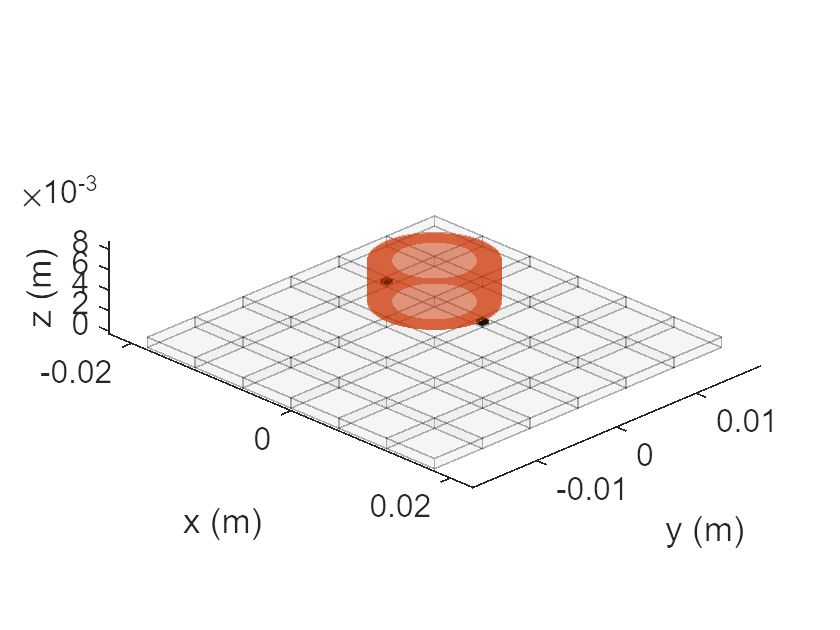

Model = struct;

vertex_file = 'Square_36mm_g6mm_node.inp';
element_file = 'Square_36mm_g6mm_element.inp';
Model = LoadHexMesh(Model, vertex_file, element_file, 1e-3);
clear vertex_file element_file

Model.conductivity = 2.38e6 * ones(1,Model.num_elms); % (S/m)

PlotWorld(EM, Sensor, Model);

## Governing Equation

GoverningEquation = BuildGoveringEquation(EM, Model);

mean(GoverningEquation.Gamma_c * GoverningEquation.V, 'all')

ans = 2.4759e-07

mean(GoverningEquation.Gamma_Ex, 'all')

ans = -1.2566e-26

mean(GoverningEquation.Gamma_Ey, 'all')

ans = 1.3387e-16

mean(GoverningEquation.Gamma_Ez, 'all')

ans = 0